# Benchmarking stable multivariate lesion symptom mapping against standard multivariate lesion symptom mapping

This tutorial demonstrates how to perform stable multivariate lesion symptom mapping, comparing it to more conventional multivariate lesion symptom mapping. In both approaches, we use a linear SVM (as implemented in matlab's statistics and machine learning toolbox) to predict some deficit. However, stable lesion symptom mapping adds a nested feature selection step, retaining only features that are stable. 

## What is lesion symptom mapping?

LSM is an approach to studying brain-behavior relationships that seeks to link the brain areas in which there is damage in a group of patients (e.g., strokes) to some deficit. The main strength of LSM compared to alternative approaches is that it permits causal inference. That is, with most other neuroimaging techniques for studying brain-behavior relationships (e.g., fMRI), the relationship that is observed is correlative. For example, say that we are interested in understanding which brain regions are involved in language. We can take a group of stroke patients and have them perform a naming task. We can then look at their patterns of blood flow to identify regions in which patients with greater language impairment show less blood flow. While this would tell us something about the areas involved in language, not all of these areas are guaranteed to be *necessary* for language. In other words, some of these area may support language without being so essential that damage to this region would impinge on language function. 

## How is lesion symptom mapping performed?

To answer that question, and also why we might expect stabSel to help us, let's start unpacking the data we will be working with. In this example, we will use stability selection to improve prediction of aphasia severity from the location of patients' lesions (this is what we call stable lesion symptom mapping). Aphasia is a complex disorder with many subtypes that share the common feature of impacting the ability of a person to communicate through language. Most strokes affect the left hemisphere, and when the injury happens in particular portions of that hemisphere, it tends to result in this disorder. 

We will be working with the Aphasia Recovery Cohort (ARC), a publicly available database of chronic stroke patients with aphasia. You can find this database here: [https://openneuro.org/datasets/ds004512/versions/2.0.0.](https://openneuro.org/datasets/ds004512/versions/2.0.0.) Note, though, the data that is publicly availabe is in something we call "native" space. That just means that each persons' brain is stored just as it was collected, reflecting their unique brain anatomy, shape, etc. In neuroimaging, the fact that everyone's brain is completely different is an enormous challange for analysis. Even though every one of us has, for instance, a Heschl's gyrus, which is a specific anatomical sturcture of the brain that is responsible for early auditory processing, every persons' Heschl's gyrus looks a little different. What's more is that even if two people had an identical heschl's gyrus, the way they happened to have been lying in the MRI while data was collected means that their gyri might be in slightly different locations in space. Thus, conventional neuroimaging analysis involves a preprocessing step where we take every one of our participants' brains and stretch, shear, and rotate them to fit a template that is representative of everyone's anatomy--a template of brain structure. 

We have done this to the majority of the participants in ARC--at least for their first visit! Note, ARC contains 25+ visits on some participants--it's a veritable treasure trove of data. To download this data please follow: 

Before we continue, please make sure:

- You have the stabSel package and its directories added to your path

- You have downloaded the data we will use and placed it (e.g., prepARC.mat and other mat files) in the stabSel directory: https://app.box.com/s/vrnyrgh3dbd9nyeo4daqo6a5k6fb0lt4

- If you want to replicate our figures, please also download our correlogram package: https://github.com/alexteghipco/Correlogram

*Note: For C-STAR folks, you can look at how the data was imported and organized into the .mat file by looking at the code at the very bottom of this file* 

To check if you have stabSel in your directory, run the following. This is also what we will use to setup some paths for later code to draw on:

% Try to look for stabSel in your path...
bd = which('stabSel.m');

% Confirm stabSel.m is in your path and add
% subdirectories to the path if you have not done that yet...
if isempty(bd)
    error('stabSel is not in your path!! Please add it to your path before proceeding...')
else
    disp('Found stabSel! This code should work just fine!')
    [bd,~,~] = fileparts(bd);
    addpath(genpath(bd))
end

% Let's also check if you have quickScatter installed (part of my
% correlogram package)
bd = which('quickScatter.m');
if isempty(bd)
    warning('Figure generation will throw an error! Please download the correlogram repository')
else
    disp('Found correlogram! Figure generation should work..')
    [bd,~,~] = fileparts(bd);
    addpath(genpath(bd))
end

## A quick example of how to load brain data for analysis with stabSel

To explain how LSM works, we will first load in all of our brain data. Now, I have nicely prepared everything for you in a .mat file called prepARC.mat which is what you downloaded above. So first, let's import that into our workspace.

try

Please select your brain mask nifti file. All nonzero values in the mask will be treated as areas of the brain you want to keep.
Trying to load using matlabs niftiread.m
Did not work! Trying to load using freesurfers load_nifti.m
Did not work! Trying to load using spm load_nifti.m
No loadable mask supplied Proceeding without the mask...
Working on file 1 of 1
File is: jhu.nii.gz
Trying to load using matlabs niftiread.m


    load([fullfile(bd, 'prepARC.mat')])
    disp('Loaded JHU atlas data (% damage within ROIs) succesfully!')
catch
    error('You either did not download the lesion data linked above or did not place it in the stabSel directory!')
end

You may have noticed that prepARC.m has a matrix called 'les', which continas our lesion data. We really only need this data, but let's say you have nifti files you would like to load in. The code below will show you how to import and nifti data for analysis.

Let's start off with a very simple example where we load a single file. The stabSel toolbox comes with a function that will help you load in all the nifti files in a single folder on your computer, using either spm, freesurfer, or matlab's imaging toolbox--whichever you happen to have installed (it will look for all 3 in a sequence). 

We are going to start off analyzing regional damage according to the JHU atlas. The stabSel toolbox comes packaged with this atlas in ./LSMAtlases/jhu. Note, the first input to brainLoad is the path to a folder that contains **all** the .nii *and *.nii.gz files that you would like to import. The second input to brainLoad is a path to a specific file which we can use as a mask. That is, only voxels that are nonzero in the mask will be pulled from each .nii and .nii.gz file being imported into matlab. We don't really care about masking our atlas so we can leave the second input as an empty variable. When an input is left empty like this, a GUI will pop up for you to select either a folder (input 1) and/or a file (input 2). In our case, we can just hit cancel when this GUI pops up, which will let brainLoad know that we aren't intending to use a mask at all.

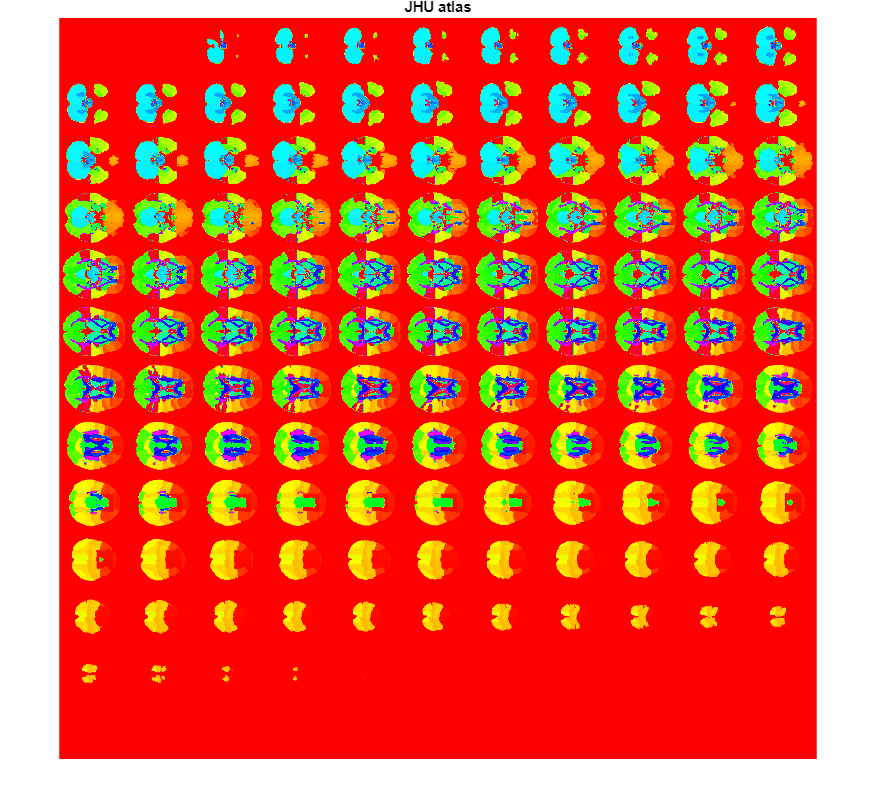

[~,jhuAtlas,~,initSz] = brainLoad(['D:\Science\Matlab\GitHub\StabilitySelection\LSMAtlases\jhu'],[]);

Now we can visualize the JHU atlas using matlab's montage function, plotting the jhuAtlas variable. One wrinkle to brainLoad is that it assumes all your nifti files are the same shape. So if youre nifti files are in different template spaces, for example, this will throw an error. Another thing about brainLoad is that it vectorizes the brain data. As long as we did not use a mask, we can reshape our brain data into a 3D matrix for functions that might expect this shape (as shown below):

jhuAtlas = reshape(jhuAtlas,initSz); % initSz contains the shape of the nifti file before vectorization so we can reshape it back into its original form

Please select your brain mask nifti file. All nonzero values in the mask will be treated as areas of the brain you want to keep.
Trying to load using matlabs niftiread.m
Did not work! Trying to load using freesurfers load_nifti.m
Did not work! Trying to load using spm load_nifti.m
No loadable mask supplied Proceeding without the mask...
Working on file 1 of 10
File is: Schaefer2018_1000Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 2 of 10
File is: Schaefer2018_100Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 3 of 10
File is: Schaefer2018_200Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 4 of 10
File is: Schaefer2018_300Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m
Working on file 5 of 10
File is: Schaefer2018_400Parcels_17Networks_order_plus_subcort.nii
Trying to load using matlabs niftiread.m


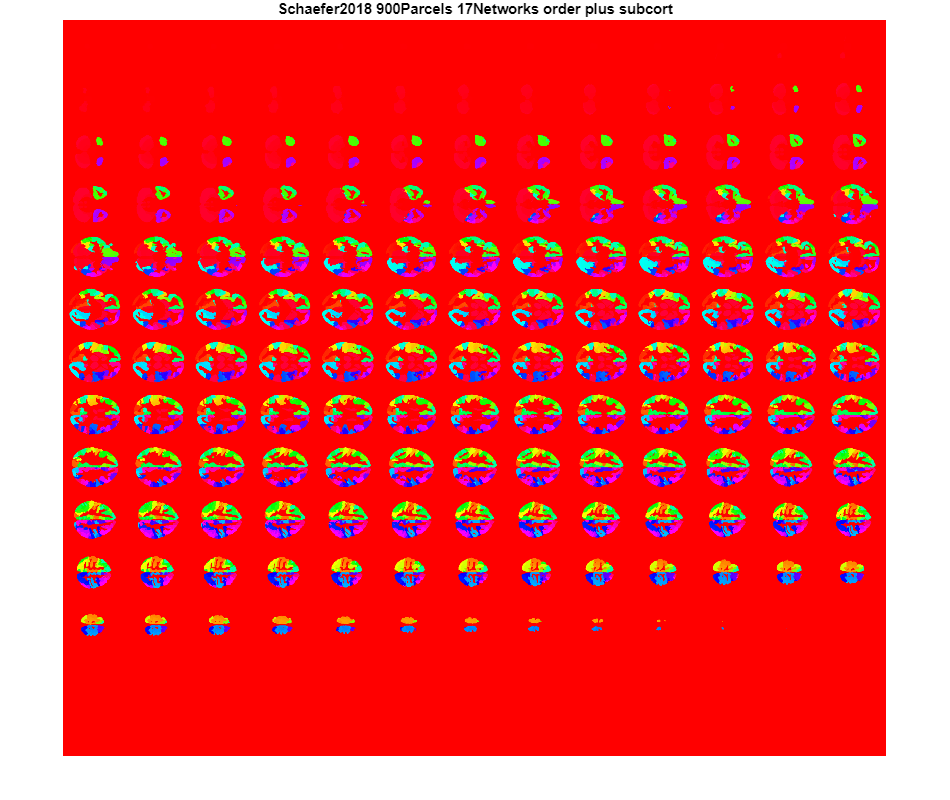

montage(jhuAtlas,'DisplayRange',[0 max(jhuAtlas(:))]); % the montage function requires the imaging toolbox, and we specify the limits based on the data (i.e., largest ROI value)
colormap(hsv) % this is a colormap to avoid boring greyscale but you can use whatever you would like
title('JHU atlas'); % a title for the montage

You can also load in multiple files at once, like so. Later on in the analysis we will use a multi-resolution atlas and we can load in that atlas now for inspection.

[fileNames,multiresAtlas,~,initSz] = brainLoad(['D:\Science\Matlab\GitHub\StabilitySelection\LSMAtlases\multires'],[]);
fileNames = extractBefore(strrep(fileNames,'_',' '),'.nii'); % here we are changing the filenames so matlab does not misinterpret underscores as subscripts for figure titles (we also remove the extension of the file)
for i = 1:length(fileNames) % we loop over files and visualize each one in a sequence. you should be able to play back the whole sequence at a slower rate in the live code
    tmp = reshape(multiresAtlas(:,i),initSz); % reshape the data as before into a 3D matrix
    ctmp = hsv(max(tmp(:))); % we need to predefine a colormap because for whatever reason, MATLAB will not update the colormap for a figure that gets overwritten multiple times inside live code
    montage(tmp,double(ctmp),'DisplayRange',[0 max(tmp(:))]); % identical montage call but here we specify the colormap values
    title(fileNames{i});
end

Note, the data we analyze with stabSel is vectorized so we would not need to reshape it, this is only necessary for visualization. You can import many files at oncer for analysis using the same code. However, I would recommend using a mask so that you have a smaller matrix to analyze. 

## Setting up inputs for analysis (excluding subjects and ROIs)

As we discussed, we're going to start by analyzing the JHU atlas, which is the initial data we loaded up. For now, we will remove the atlas files we experimented with in loading nifti files for stabSel since the data has already been organized for us. We will then remove subjects with lesions that do not overlap with our specific atlas (e.g., you can imagine that some atlases won't have the same coverage, like subcortical regions, etc), and remove regions in the atlas that show no damage in our sample. 

clearvars -except les beh labs
X = les; % we will rename our variables for simplicity. X is our predictor matrix but we have one matrix for each atlas
y = beh.wab_r_aq; % this is our response variable y, or aphasia severity. For now, we keep one per atlas because it is possible for atlases to have a different number of subjects based on the way we are processing the data
z = beh.lesVol; % this is arguably our nuissance variable, lesion volume, or z

% remove empty participants (no lesion overlap with any ROI in atlas)
tor = []; % this is the vector of participants to remove that we will track
for j = 1:size(X,2)
    if sum(X(:,j)) == 0
        tor = [tor; j];
    end
end
% we need to make sure to remove participants across all our variables
y(tor) = [];
z(tor) = [];
X(:,tor) = [];

% now find participants with missing behavior
tor = find(isnan(y));
y(tor) = [];
z(tor) = [];
X(:,tor) = [];

% find ROIs with no damage in any participant
tor = [];
for j = 1:size(X,1)
    if sum(X(j,:)) == 0
        tor = [tor; j];
    end
end
X(tor,:) = [];
labs(tor,:) = [];

% now remove rois represented by fewer than 10 participants
clear rid2 rid
for j = 1:size(X,1)
    rid2(j) = length(find(X(j,:) ~= 0));
end
rid = find(rid2 <= 10);
X(rid,:) = [];
labs(rid,:) = [];

X = X';
clear rid rid2 tor beh j

## Setting up a cross-validation scheme

We now need to set up a cross validation scheme for our analysis. This will ensure that when we build our stable multivariate lesion symptom mapping (sMLSM) and standard multivariate lesion symptom mapping models (MLSM), we will always have external data for testing model accuracy. 

To set this up, we will use matlab's cvpartition function. We will use this to setup 10 outer folds and will repeat cross validation 11 times. One trick we'll use is to pretend we are doing classification so that we can stratify our folds by lesion size. This is so that we can ensure each training dataset gets consistent exposure to lesions of varying size (at least in a crude way, based on categories we will define from lesion size).

% Create lesion size quantiles from our data
q = quantile(z,[0.25 0.5 0.75]); 
cat = zeros(1,length(z));
cat(z <= q(1)) = 1; %1st lesion size category (<= 1st quartile)
cat(z > q(1) & z <= q(2)) = 2; % 2nd lesion size category (> 1st quartile and <= median)
cat(z > q(2) & z <= q(3)) = 3; % 3rd lesion size category (> median and <= 3rd quartile)
cat(z > q(3)) = 4; % 4th lesion size category (> 3rd quartile)

------WORKING ON REPEAT: 1 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 10.2507
Probability threshold for features to enter stable set was calculated to be: 1.1913
Number of features in the s

------WORKING ON REPEAT: 2 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 10.8578
Probability threshold for features to enter stable set was calculated to be: 1.2756
Number of features in the s

------WORKING ON REPEAT: 3 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 11.7543
Probability threshold for features to enter stable set was calculated to be: 1.409
Number of features in the st

------WORKING ON REPEAT: 4 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 11.5159
Probability threshold for features to enter stable set was calculated to be: 1.3725
Number of features in the s

------WORKING ON REPEAT: 5 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 25
Working on subsample 2 of 25
Working on subsample 3 of 25
Working on subsample 4 of 25
Working on subsample 5 of 25
Working on subsample 6 of 25
Working on subsample 7 of 25
Working on subsample 8 of 25
Working on subsample 9 of 25
Working on subsample 10 of 25
Working on subsample 11 of 25
Working on subsample 12 of 25
Working on subsample 13 of 25
Working on subsample 14 of 25
Working on subsample 15 of 25
Working on subsample 16 of 25
Working on subsample 17 of 25
Working on subsample 18 of 25
Working on subsample 19 of 25
Working on subsample 20 of 25
Working on subsample 21 of 25
Working on subsample 22 of 25
Working on subsample 23 of 25
Working on subsample 24 of 25
Working on subsample 25 of 25
Empirical maxVars (actual average # of selected features across parameters) was: 10.5786
Probability threshold for features to enter stable set was calculated to be: 1.2362
Number of features in the s


for j = 1:11 % we will make 11 random partitions stratified by our lesion quartiles...
    c{j} = cvpartition(cat,"KFold",10,"Stratify",true);
end

## Stable multivariate lesions symptom mapping leverages stability selection and requires setting some hyperparameters

Let's start by building some preliminary stable multivariate lesion symptom mapping (sMLSM) models since these will be the main emphasis of the current tutorial. The point of sMLSM is to introduce a robust feature selection step into a more standard MLSM pipeline. This step will be introduced in a nested fashion (more on that later). What's important to point out for now is that in sMLSM, we use a specific kind of feature selection: stability selection. This framework for feature selection is very flexible but has many potential settings that you can change. 

Here, we will focus on a very simple implementation of this framework, in line with the original studies that proposed it. This means the following: 

- In sMLSM, we will create hundreds of perturbed datasets using subsamples (other options are available but this for simplicity and to be faithful to the original stability selection study, we stick with subsampling)

- For each perturbed dataset, we will perform feature selection using an algorithm of our choosing. Again, many options are available. But here, we will use an algorithm very close to what was used wtih the original stability selection proposal: elastic net. While the original approach was applied to lasso, we use elastic net because it should be more consistent (e.g., when features are correlated it will **not** tend to randomly select one of multiple correlated features like lasso)

- On each perturbed dataset, we select some number of features (e.g., half of the entire feature set)

- We will tally up the number of times each feature was selected across perturbed datasets to generate stability scores (i.e., the proportion of datasets in which a feature was selected). Note, we do this for every hyperparameter in a specified range for elastic net and then take the highest stability score across hyperparameters. For elastic net, we use a reasonable default set of hyperparameters (more on that later).

- We will then find a "stable" set of features by identifying a threshold for stability scores that attempts to ensure an upper bound on the  number of false positives in the stable set. The proportion of false positives to the size of the stable set represents the per family error rate. The per comparison error rate roughly corresponds to a halving of the per family error rate. 

As you can see from above, the main hyperparameters that we have to choose for sMLSM are: 1) the hyperparameter sequences to use for our feature selection algorithm, 2) the number of features to select for each perturbed dataset, 3) the number of false positives we are comfortable with in our stable set. 

Here, we will not focus on points (1) and (2) because it increases the complexity of the analyses. We'll address this in another tutorial and use some reasonable defaults for now. But note also that some studies have suggested these variables should not make a terribly huge impact on the results. 

Turning to the last two points, we will now run an analysis to try to understand how many subsamples are required for stability scores to become more consistent. We will later run an analyses to understand how changing the number of false positives can influence outcome. 

# A preliminary analysis: getting the hang of stable multivariate lesions symptom mapping (sMLSM) by evaluating the consistency of stability selection

Let's get straight into it! Here, we will start with an arbitrary but reasonable number of false positives and use a measly 25 repeated perturbations of our data. The idea is that we will look at the consistency of stability scores across repeats of the entire feature analysis pipeline.

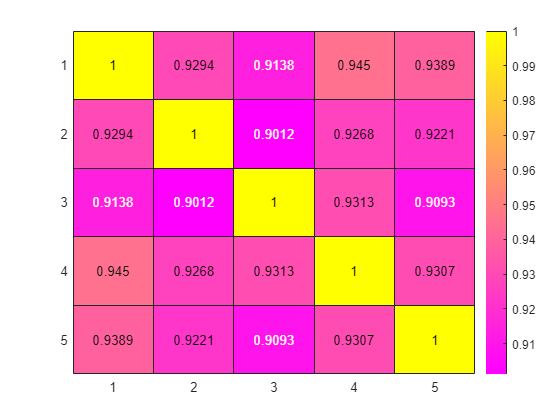

for i = 1:5

    disp(['------WORKING ON REPEAT: ' num2str(i) ' of ' num2str(5)])
    [fk{i},~,fscmx(:,i),~,~,~,~,~,~,~,~,empMaxVars{i},~,~,~] = stabSel(X,y,'selAlgo','en',...
        'samType','subsample','rep',25,'compPars',false,'numFalsePos',1,'maxVars',...
        size(X,2)/2,'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
end

------WORKING ON REPEAT: 1 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 300
Working on subsample 2 of 300
Working on subsample 3 of 300
Working on subsample 4 of 300
Working on subsample 5 of 300
Working on subsample 6 of 300
Working on subsample 7 of 300
Working on subsample 8 of 300
Working on subsample 9 of 300
Working on subsample 10 of 300
Working on subsample 11 of 300
Working on subsample 12 of 300
Working on subsample 13 of 300
Working on subsample 14 of 300
Working on subsample 15 of 300
Working on subsample 16 of 300
Working on subsample 17 of 300
Working on subsample 18 of 300
Working on subsample 19 of 300
Working on subsample 20 of 300
Working on subsample 21 of 300
Working on subsample 22 of 300
Working on subsample 23 of 300
Working on subsample 24 of 300
Working on subsample 25 of 300
Working on subsample 26 of 300
Working on subsample 27 of 300
Working on subsample 28 of 300
Working on subsample 29 of 300
Working on subsample 30 of 300
Working on subsample

------WORKING ON REPEAT: 2 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 300
Working on subsample 2 of 300
Working on subsample 3 of 300
Working on subsample 4 of 300
Working on subsample 5 of 300
Working on subsample 6 of 300
Working on subsample 7 of 300
Working on subsample 8 of 300
Working on subsample 9 of 300
Working on subsample 10 of 300
Working on subsample 11 of 300
Working on subsample 12 of 300
Working on subsample 13 of 300
Working on subsample 14 of 300
Working on subsample 15 of 300
Working on subsample 16 of 300
Working on subsample 17 of 300
Working on subsample 18 of 300
Working on subsample 19 of 300
Working on subsample 20 of 300
Working on subsample 21 of 300
Working on subsample 22 of 300
Working on subsample 23 of 300
Working on subsample 24 of 300
Working on subsample 25 of 300
Working on subsample 26 of 300
Working on subsample 27 of 300
Working on subsample 28 of 300
Working on subsample 29 of 300
Working on subsample 30 of 300
Working on subsample

------WORKING ON REPEAT: 3 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 300
Working on subsample 2 of 300
Working on subsample 3 of 300
Working on subsample 4 of 300
Working on subsample 5 of 300
Working on subsample 6 of 300
Working on subsample 7 of 300
Working on subsample 8 of 300
Working on subsample 9 of 300
Working on subsample 10 of 300
Working on subsample 11 of 300
Working on subsample 12 of 300
Working on subsample 13 of 300
Working on subsample 14 of 300
Working on subsample 15 of 300
Working on subsample 16 of 300
Working on subsample 17 of 300
Working on subsample 18 of 300
Working on subsample 19 of 300
Working on subsample 20 of 300
Working on subsample 21 of 300
Working on subsample 22 of 300
Working on subsample 23 of 300
Working on subsample 24 of 300
Working on subsample 25 of 300
Working on subsample 26 of 300
Working on subsample 27 of 300
Working on subsample 28 of 300
Working on subsample 29 of 300
Working on subsample 30 of 300
Working on subsample

------WORKING ON REPEAT: 4 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 300
Working on subsample 2 of 300
Working on subsample 3 of 300
Working on subsample 4 of 300
Working on subsample 5 of 300
Working on subsample 6 of 300
Working on subsample 7 of 300
Working on subsample 8 of 300
Working on subsample 9 of 300
Working on subsample 10 of 300
Working on subsample 11 of 300
Working on subsample 12 of 300
Working on subsample 13 of 300
Working on subsample 14 of 300
Working on subsample 15 of 300
Working on subsample 16 of 300
Working on subsample 17 of 300
Working on subsample 18 of 300
Working on subsample 19 of 300
Working on subsample 20 of 300
Working on subsample 21 of 300
Working on subsample 22 of 300
Working on subsample 23 of 300
Working on subsample 24 of 300
Working on subsample 25 of 300
Working on subsample 26 of 300
Working on subsample 27 of 300
Working on subsample 28 of 300
Working on subsample 29 of 300
Working on subsample 30 of 300
Working on subsample

------WORKING ON REPEAT: 5 of 5


Preallocating subsample indices
Starting feature selection. Working on resample 1 of 300
Working on subsample 2 of 300
Working on subsample 3 of 300
Working on subsample 4 of 300
Working on subsample 5 of 300
Working on subsample 6 of 300
Working on subsample 7 of 300
Working on subsample 8 of 300
Working on subsample 9 of 300
Working on subsample 10 of 300
Working on subsample 11 of 300
Working on subsample 12 of 300
Working on subsample 13 of 300
Working on subsample 14 of 300
Working on subsample 15 of 300
Working on subsample 16 of 300
Working on subsample 17 of 300
Working on subsample 18 of 300
Working on subsample 19 of 300
Working on subsample 20 of 300
Working on subsample 21 of 300
Working on subsample 22 of 300
Working on subsample 23 of 300
Working on subsample 24 of 300
Working on subsample 25 of 300
Working on subsample 26 of 300
Working on subsample 27 of 300
Working on subsample 28 of 300
Working on subsample 29 of 300
Working on subsample 30 of 300
Working on subsample

Now let's see how consistent our feature selection probabilities are (i.e., assignment of stability scores) in a relatively crude but intuitive way--by correlating probabilities across repeats

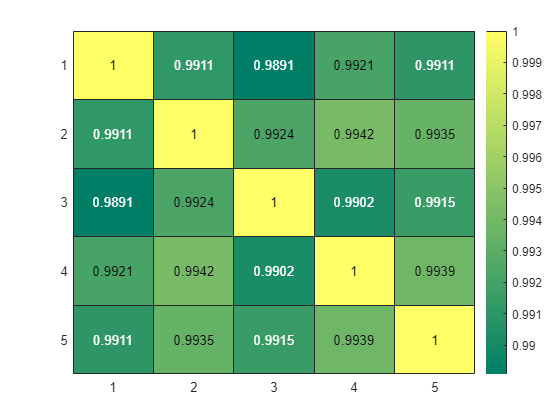

[r,~] = corr(fscmx);
figure; h = heatmap(r);
colormap('spring')

Looks like we're getting some decently consistent feature stability assignments! About 25 resamples is what has been originally recommended to use with stability selection. But can we make this better? Let's try a more reasonable number of resamples...

for i = 1:5
    disp(['------WORKING ON REPEAT: ' num2str(i) ' of ' num2str(5)])
    [fk2{i},~,fscmx2(:,i),~,~,~,~,~,~,~,~,empMaxVar2s{i},~,~,~] = stabSel(X,y,'selAlgo','en',...
        'samType','subsample','rep',300,'compPars',false,'numFalsePos',1,'maxVars',...
        size(X,2)/2,'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
end

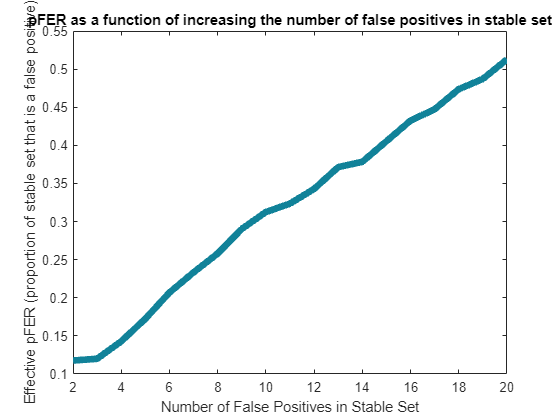

[r2,~] = corr(fscmx2);

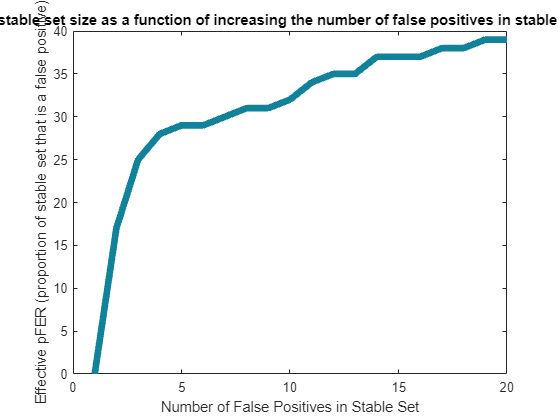

figure; h = heatmap(r2);
colormap('summer')

I know that took some time to run but it was worth it! You should now see correlations of ~0.99+

## Manipulating stable set definition after running stabSel

If you looked at the documentation for stabSel you may have noticed that it automatically computes the stable set of features based on a preselected number of false positives. The problem with this approach is that you don't know ahead of time how large the stable set will be, so your preselected number of false positives may correspond to a per family or per comparison rate that is too high or too low. 

We can solve this issue after running stabSel because all we need are the stability scores to manipulate our pFER/pCER. Here is a snippet of code that allows you to change the stable set. Below, we will use it to show how the size of the sstable set changes as we manipulate the number of false positives in the stable set

% now let's manipulate our number of false positives. To get an even more
% stable set of scores we will take the mean stability score over all our
% repeats
for i = 1:20
    t = ((((mean(cell2mat(empMaxVar2s)).^2)/size(X,2))/i)+1)/2; % formula for computing feature selection probability threshold given the average number of features selected across resampled datasets
    epfer(i,1) = i./length(find(mean(fscmx2,2) > t)); % if you took the indices of fscmx > t you would get the new stable set
    epferLen(i,1) = length(find(mean(fscmx2,2) > t));
end
figure; plot(epfer,'Color',[0.0667    0.5098    0.6000],'LineWidth',5);xlabel('Number of False Positives in Stable Set'); ylabel('Effective pFER (proportion of stable set that is a false positive)')
title('pFER as a function of increasing the number of false positives in stable set')
figure; plot(epferLen,'Color',[0.0667    0.5098    0.6000],'LineWidth',5);xlabel('Number of False Positives in Stable Set'); ylabel('Effective pFER (proportion of stable set that is a false positive)')
title('stable set size as a function of increasing the number of false positives in stable set')

# Now that you've gotten the hang of stability selection, let's actually run stable multivariate lesion symptom mapping on the JHU atlas

We will dissociate the portion of sMLSM where we perform feature selection and the portion where we build our MLSM model. We do this so that the process becomes conceptually easier to grasp and so that it's easier to save out portions of the pipeline if something goes wrong (note, this will take quite some time to run!!!). If you prefer, you can nest stability selection and MLSM in one single loop.

clearvars -except X y z c
runStabSel = false; % change this to true if you would like to run stability selection, otherwise you can load in our run!
if runStabSel
    for r = 1:length(c)
        for i = 1:c{r}.NumTestSets
            disp(['Working on outer fold:' num2str(i)])
            [fkRaw{r}{i},~,probRaw{r}{i},~,~,~,~,~,~,~,~,empMaxVarsRaw{r}{i},~,~,~] = stabSel([X(training(c{r},i),:) z(training(c{r},i))],y(training(c{r},i)),'selAlgo','en',...
                'samType','subsample','rep',500,'compPars',false,'numFalsePos',3,'maxVars',30,'keepScores',false,...
                'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
        end
        try
            save('JHU_stabSel_results.mat');
        catch
            save('JHU_stabSel_results.mat','-v7.3');
        end
    end
else
    load('JHU_stabSel_results.mat');
end

Now let's build a MLSM model using our stable features. One thing we will experiment with is understanding how the sMLSM model performance changes when we manipulate the number of false positives that we are comfortable with. We will also compare these models to a baseline model that just uses lesion size.

runsMLSM = true;
if runsMLSM
    tot = 30; % this is the max number of false positives we will test: 1...tot
    for r = 1:length(fkRaw{a}{i}) % loop over repeats of CV...
        disp(num2str(r))
        for n = 1:tot % loop over sequence of false positives
            for i = 1:length(fkRaw{r}) % test set

                % first define your new stable set...
                t = ((((empMaxVarsRaw{r}{i}.^2)/size(X,1))/n)+1)/2; % compute the new stability threshold
                fkfin{i}{r}{n} = find(probRaw{r}{i} > t); % find new stable set

                % now train a lesion size only model--note, we use fitlm
                % here for speed but using a linear SVM will not change the
                % results
                bmdlLV{i} = fitlm(z(training(c{r},i)),y(training(c{r},i)),'RobustOpts','on');

                % get lesion size model predictions
                yhatLV(test(c{r},i),r) = predict(bmdlLV{i},z(test(c{r},i)));

                % also get training dataset-based naive predictions
                guessLV(test(c{r},i),r) = mean(y(training(c{r},i)));

                % definte hyperparameters for MLSM (we use linear SVM)
                hype = hyperparameters('fitrsvm',[X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],y(training(c{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800]; %200
                hype(4).Optimize = true;

                % Now we need to run a SVM on stable features plus lesion
                % size (sMLSM model)
                bmdlAF{i,r,n} = fitrsvm([X(training(c{r},i),fkfin{i}{r}{n}) z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                    'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
                % Get sMLSM model predictions

1
2
3
4
5
6
7
8
9
10
11


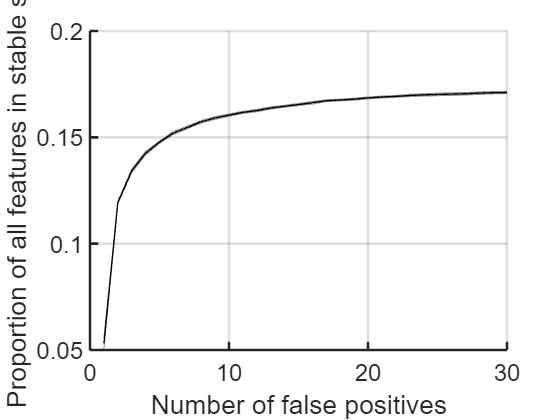

                yhatAF(test(c{r},i),r,n) = predict(bmdlAF{i,r,n},[X(test(c{r},i),fkfin{i}{r}{n}) z(test(c{r},i))]);

                % now get one last control model--here we use all the
                % features
                hype = hyperparameters('fitrsvm',[X(training(c{r},i),:) z(training(c{r},i))], y(training(c{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800]; %200
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                hype = hyperparameters('fitrsvm',[X(training(c{r},i),:) z(training(c{r},i))],y(training(c{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800]; %200
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                bmdlAFc{r,i} = fitrsvm([X(training(c{r},i),:) z(training(c{r},i))],y(training(c{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                    'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
                yhatAFc(test(c{r},i),r) = predict(bmdlAFc{r,i},[X(test(c{r},i),:) z(test(c{r},i))]);

            end


            % compute various performance measures for each MLSM model
            [AFc_corr(r,1),AFc_corrp(r,1)] = corr(yhatAFc(:,r),y);
            AFc_mae(r,1) = mean(abs(y-yhatAFc(:,r)));
            AFc_mase(r,1) = AFc_mae(r,1) ./ mean(abs(y-guessLV(:,r)));
            AFc_ap(r,1) = (1-AFc_mase(r,1))*100;

            % compute various performance measures for each sMLSM model
            [AF_corr(r,n),AF_corrp(r,n)] = corr(yhatAF(:,r,n),y);
            AF_mae(r,n) = mean(abs(y-yhatAF(:,r,n)));
            AF_mase(r,n) = AF_mae(r,n) ./ mean(abs(y-guessLV(:,r)));
            AF_ap(r,n) = (1-AF_mase(r,n))*100;
        end
        
        % compute various performance measures for the lesion size only model
        [lsz_corr(r,1),lsz_corrp(r,1)] = corr(yhatLV(:,r),y);
        lsz_mae(r,1) = mean(abs(y-yhatLV(:,r)));
        lsz_mase(r,1) = lsz_mae(r,1) ./ mean(abs(y-guessLV(:,r)));
        lsz_ap(r,1) = (1-lsz_mase(r,1))*100;
        try

1
2
3
4
5
6
7
8
9
10
11


            save('JHU_sMLSM_results.mat');
        catch
            save('JHU_sMLSM_results.mat','-v7.3');
        end
    end
else
    load('JHU_sMLSM_results.mat');
end

## Now let's plot model accuracies as a function of pFER set for stability selection

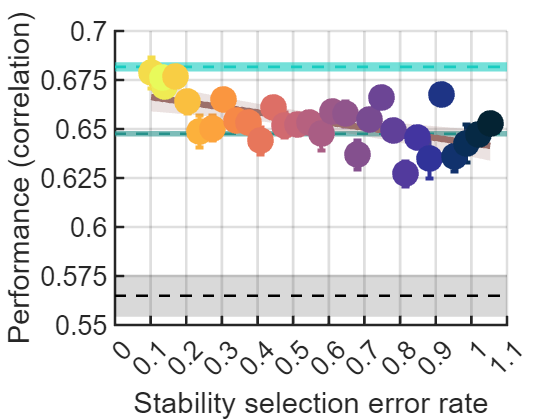

% get mean and SEM for all models...
AFc_corr_m = mean(AFc_corr);
AFc_corr_sem = std(AFc_corr)./sqrt(length(AFc_corr));
AFc_ap_m = mean(AFc_ap);
AFc_ap_sem = std(AFc_ap)./sqrt(length(AFc_ap));
AF_corr_a = AF_corr; % here I was combining a few additional repeats run on a different computer which is why we redefine some variables...
AF_ap_a = AF_ap;

AF_corr_a_m = mean(AF_corr_a);
AF_ap_a_m = mean(AF_ap_a);
AF_corr_a_sem = std(AF_corr_a)./sqrt(length(AF_corr_a));
AF_ap_a_sem = std(AF_ap_a)./sqrt(length(AF_corr_a));

AF_corr_m = mean(AF_corr);
AF_ap_m = mean(AF_ap);

AF_corr_sem = std(AF_corr)./sqrt(length(AF_corr));
AF_ap_sem = std(AF_ap)./sqrt(length(AF_corr));

lsz_corr_m = mean(lsz_corr);
lsz_ap_m = mean(lsz_ap);

lsz_corr_sem = std(lsz_corr)./sqrt(length(lsz_corr));
lsz_ap_sem = std(lsz_ap)./sqrt(length(lsz_ap));


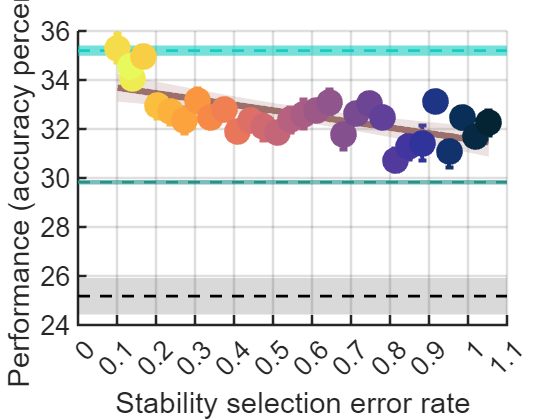

% Now compute stable set sizes, pFER and pCER
for a = 1:length(fkRaw)
    disp(num2str(a))
    for n = 1:30
        for i = 1:length(fkRaw{a}) % test set
            nfk(a,i,n) = length(fkfin{i}{a}{n});
            ep(a,i,n) = n./nfk(a,i,n);
            ep2(a,i,n) = (n/2)./nfk(a,i,n);
        end
    end
end
% fix stable set sizes of zero
id = find(isinf(ep));
ep(id) = NaN;
id = find(isinf(ep2));
ep2(id) = NaN;

% get mean and sem for pfer, pcer, stable set size
nfk_m = squeeze(mean(mean(nfk,2,'omitnan'),1,'omitnan'))';
pfer_m = squeeze(mean(mean(ep,2,'omitnan'),1,'omitnan'))';
pcer_m = squeeze(mean(mean(ep2,2,'omitnan'),1,'omitnan'))';

nfk_sem = squeeze(std(mean(nfk,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1));
pfer_sem = squeeze(std(mean(ep,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1));

pcer_sem = squeeze(std(mean(ep2,2,'omitnan'),[],1,'omitnan'))'./sqrt(size(squeeze(mean(nfk,2,'omitnan')),1));

% plot of the number of features in the stable set...
tmp = nfk_m(1:30)./size(X,1);
tmp2 = nfk_sem./size(X,1);
figure; plt1 = shadedErrorBar([1:30],tmp,[tmp-tmp2; tmp+tmp2]);
box off; set(gcf,'color','w'); ax = gca; ax.LineWidth = 2; grid on; set(gca,'TickLength',[0.02 0.02]); set(gca,'FontSize',18)
xlabel('Number of false positives')
ylabel('Proportion of all features in stable set')

ax =   Axes with properties:

             XLim: [-6.9283 100]
             YLim: [-13.0494 100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1675 0.2421 0.7375 0.6829]
            Units: 'normalized'

  Show all properties


#### Now we should get "tuned" models. Because we saved out all the models, we can now compare the error for each number of false positives we used to build the model

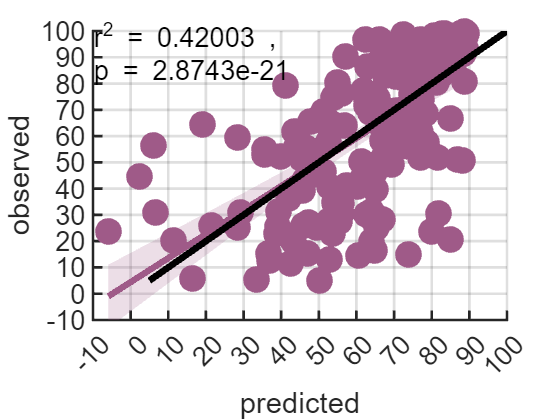

clear moderr moderrw yhatAFT nfpWinner
tot = 30;
for r = 1:length(fkRaw) % repeats
    disp(num2str(r))

    for i = 1:length(fkRaw{r}) % test set
        % for i, which n wins?'
        for n = 1:tot % extract model loss
            moderr(n,1) = bmdlAF{i,r,n}.HyperparameterOptimizationResults.MinEstimatedObjective;
        end
        moderrw = moderr .* (1 + 0.002 .* [1:length(moderr)]'); % linearly weight the loss slightly to favor lower pFER by favoring a smaller number of false positives. Note, we use this weighting across ALL analyses in our manuscript, including when testing other sample sizes and atlases

ax =   Axes with properties:

             XLim: [-50 100]
             YLim: [-50 100]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1675 0.2421 0.7375 0.6829]
            Units: 'normalized'

  Show all properties


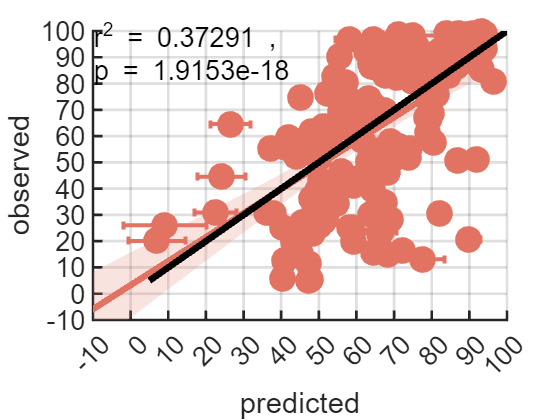

        [mv,nfpWinner(i,r)] = min(moderrw);       
        yhatAFT(test(c{r},i),r) = predict(bmdlAF{i,r,nfpWinner(i,r)},[X(test(c{r},i),fkfin{i}{r}{nfpWinner(i,r)}) z(test(c{r},i))]);
    end
    [AF_corrT(r,1),AF_corrpT(r,1)] = corr(yhatAFT(:,r),y);

    AF_maeT(r,1) = mean(abs(y-yhatAFT(:,r)));
    AF_maseT(r,1) = AF_maeT(r,1) ./ mean(abs(y-guessLV(:,r)));
    AF_apT(r,1) = (1-AF_maseT(r,1))*100;
end
AF_corrT_m = mean(AF_corrT);
AF_apT_m = mean(AF_apT);

ax =   Axes with properties:

             XLim: [0 100.8433]
             YLim: [0 102.9285]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1675 0.2421 0.7375 0.6829]
            Units: 'normalized'

  Show all properties



AF_corrT_sem = std(AF_corrT)./length(AF_corrT);
AF_apT_sem = std(AF_apT)./length(AF_corrT);

#### Now we can plot! Model performance (y-axis) as a function of number of false positives (color)  and pFER (x-axis)

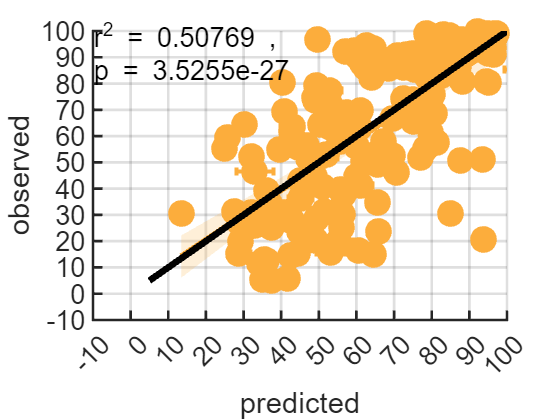

figure; plt1 = shadedErrorBar([0 1.1],[AFc_corr_m AFc_corr_m],repmat([AFc_corr_m-AFc_corr_sem AFc_corr_m+AFc_corr_sem]',1,2));

plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
hold on
plt2 = shadedErrorBar([0 1.1],[lsz_corr_m lsz_corr_m],repmat([lsz_corr_m-lsz_corr_sem lsz_corr_m+lsz_corr_sem]',1,2));
plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
plt2.patch.FaceColor = plt2.mainLine.Color;
plt2.patch.FaceAlpha = 0.6;

plt3 = shadedErrorBar([0 1.1],[AF_corrT_m AF_corrT_m],repmat([AF_corrT_m-AF_corrT_sem AF_corrT_m+AF_corrT_sem]',1,2));
plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
plt3.patch.FaceColor = plt3.mainLine.Color;
plt3.patch.FaceAlpha = 0.6;

[parts] = quickScatter(AF_corr_m(1:30),pfer_m(1:30),'perfectY',false,'useWholeMap',true,'err',[AF_corr_sem(1:30); pfer_sem(1:30)]','markerAlpha',1,'newFig',false);
parts.annot.Visible = 'off';
ax = gca;
ax.XTick = [0:0.1:1.1];
xlim([0 1.1]);
ax.YTick = [0.55:0.025:0.7];
xlabel('Stability selection error rate')
ylabel('Performance (correlation)')
% ap
figure; plt1 = shadedErrorBar([0 1.1],[AFc_ap_m AFc_ap_m],repmat([AFc_ap_m-AFc_ap_sem AFc_ap_m+AFc_ap_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
hold on
plt2 = shadedErrorBar([0 1.1],[lsz_ap_m lsz_ap_m],repmat([lsz_ap_m-lsz_ap_sem lsz_ap_m+lsz_ap_sem]',1,2));
plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
plt2.patch.FaceColor = plt2.mainLine.Color;
plt2.patch.FaceAlpha = 0.6;
plt3 = shadedErrorBar([0 1.1],[AF_apT_m AF_apT_m],repmat([AF_apT_m-AF_apT_sem AF_apT_m+AF_apT_sem]',1,2));
plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
plt3.patch.FaceColor = plt3.mainLine.Color;
plt3.patch.FaceAlpha = 0.6;
[parts] = quickScatter(AF_ap_m(1:30),pfer_m(1:30),'perfectY',false,'useWholeMap',true,'err',[AF_ap_sem(1:30); pfer_sem(1:30)]','markerAlpha',1,'newFig',false);
parts.annot.Visible = 'off';
ax = gca;
ax.XTick = [0:0.1:1.1];
xlim([0 1.1]);
xlabel('Stability selection error rate')
ylabel('Performance (accuracy percent)')

## Scatter plots of each type of models' performance (as an ensemble)

% lesion size only
sd = std(yhatLV,[],2)./sqrt(11);
m = mean(yhatLV,2);
[parts] = quickScatter(y,m,'perfectY',true','markerAlpha',1,'colorIndex',7,'err',[zeros(size(sd)) sd]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax = gca;
ax.XTick = [-10:10:100];
xlim([-10 100]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax.YTick = [-10:10:100];
ylim([-10 100]);
% all features
sd = std(yhatAFc,[],2)./sqrt(11);
m = mean(yhatAFc,2);
[parts] = quickScatter(y,m,'perfectY',true','markerAlpha',1,'colorIndex',5,'err',[zeros(size(sd)) sd]);
ax = gca;
ax.XTick = [-10:10:100];
xlim([-10 100]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax.YTick = [-10:10:100];
ylim([-10 100]);
% tuned
sd = std(yhatAFT,[],2)./sqrt(11);
m = mean(yhatAFT,2);
[parts] = quickScatter(y,m,'perfectY',true','markerAlpha',1,'colorIndex',3,'err',[zeros(size(sd)) sd]);
ax = gca;
ax.XTick = [-10:10:100]
xlim([-10 100]);
parts.annot.Position = [0.1500    0.9000    0.3504    0.0631];
ax.YTick = [-10:10:100];
ylim([-10 100])

# Varying the sample size over dozens of repeats of cross validation

You could also imagine subsampling the dataset many times with different sample sizes to understand how adding more samples to the model influences performance. Here's how you might adapt the code above to do this

clearvars -except X y z
X = X'; % we flip the matrix for the code below but you could easily rewrite this

% get random subsamples and rerun stabSel on them
smpsz = [35:20:165]; % define our sample sizes to test
for r = 1:50
    for s = 1:length(smpsz)
        smpc{s,r} = cvpartition(cat,"Holdout",smpsz(s)./size(X,2),'Stratify',true);
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        c2{s,r} = cvpartition(size(X2,1),"KFold",10);
        for i = 1:c2{s,r}.NumTestSets
            disp(num2str(i))
            [fkRaw{r}{s}{i},~,probRaw{r}{s}{i},~,~,~,~,~,~,~,~,empMaxVarsRaw{r}{s}{i},~,~,~] = stabSel(X2(training(c2{s,r},i),:),y2(training(c2{s,r},i))','selAlgo','en',...
                'samType','subsample','rep',300,'compPars',false,'numFalsePos',3,'maxVars',size(X2,2)./2,'keepScores',false,...
                'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.1:1],'fixMax',true,'prop',0.5,'verbose',true);
        end
        save('smpSz_analysis.mat')
    end                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       
end

tot = 20;
ym = mean(y);
for r = 1:60 % number of repeats of CV for each sample size
    disp(num2str(r))
    for s = 1:length(smpsz)
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        z2 = z(test(smpc{s,r},1))';
        for n = 1:tot
            for i = 1:10 % test set
                % first define your features...
                t = ((((empMaxVarsRaw{r}{s}{i}.^2)/size(X2,1))/n)+1)/2;
                fkfin{i}{r}{s}{n} = find(probRaw{r}{s}{i} > t);
                id = find(fkfin{i}{r}{s}{n} > size(X2,1));
                fkfin{i}{r}{s}{n}(id) = [];

                if isempty(fkfin{i}{r}{s}{n})
                    fkfin{i}{r}{s}{n} = [1:size(X2,2)];
                end

                % also get training dataset-based naive predictions
                guessLV{r}(test(c2{s,r},i),1) = mean(y2(training(c2{s,r},i)));

                hype = hyperparameters('fitrsvm',[X2(training(c2{s,r},i),fkfin{i}{r}{s}{n}) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800];
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                bmdlAF = fitrsvm([X2(training(c2{s,r},i),fkfin{i}{r}{s}{n}) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r} ,i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName','expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

                errTrack(r,s,n,i) = bmdlAF.HyperparameterOptimizationResults.MinEstimatedObjective;
                yhatAF{r}{s}{n}(test(c2{s,r},i),1) = predict(bmdlAF,[X2(test(c2{s,r},i),fkfin{i}{r}{s}{n}) z2(test(c2{s,r} ,i))']);
            end
            [AF_corr(r,s,n),AF_corrp(r,s,n)] = corr(yhatAF{r}{s}{n}(:,1),y2');
            AF_mae(r,s,n) = mean(abs(y2'-yhatAF{r}{s}{n}(:,1)));
            AF_mase(r,s,n) = AF_mae(r,s,n) ./ mean(abs(y2-guessLV{r}(:,1)'));
            AF_ap(r,s,n) = (1-AF_mase(r,s,n))*100;
        end
        save('smpsz_analysis_models.mat','-v7.3') % 2 includes error for tuning...
    end
end

% let's not forget to run baseline models with varying sample sizes...
clear guessLV
for r = 1:60
    disp(num2str(r))
    for s = 1:length(smpsz)
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        z2 = z(test(smpc{s,r},1))';
        for i = 1:10 % test set
           
            % also get training dataset-based naive predictions
            guessLV{r}{s}(test(c2{s,r},i),1) = mean(y2(training(c2{s,r},i)));

            hype = hyperparameters('fitrsvm',z2(training(c2{s,r} ,i))',y2(training(c2{s,r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to run a SVM on *all* features plus lesion size
            bmdlAF = fitrsvm(z2(training(c2{s,r} ,i))',y2(training(c2{s,r} ,i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName','expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

            yhatAFL{r}{s}(test(c2{s,r},i),1) = predict(bmdlAF,z2(test(c2{s,r} ,i))');
        end
        [AF_corrL(r,s),AF_corrpL(r,s)] = corr(yhatAFL{r}{s}(:,1),y2');
        AF_maeL(r,s) = mean(abs(y2'-yhatAFL{r}{s}(:,1)));
        AF_maseL(r,s) = AF_maeL(r,s) ./ mean(abs(y2-guessLV{r}{s}(:,1)'));
        AF_apL(r,s) = (1-AF_maseL(r,s))*100;
        save('smpsz_analysis_control.mat') %
    end
end

% and now an all feature model...
for r = 1:60
    disp(num2str(r))
    for s = 1:length(smpsz)
        X2 = X(:,test(smpc{s,r},1))';
        y2 = y(test(smpc{s,r},1))';
        z2 = z(test(smpc{s,r},1))';
        for i = 1:10 % test set
           
            hype = hyperparameters('fitrsvm',[X2(training(c2{s,r},i),:) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r},i)));
            hype(2).Optimize = false;
            hype(1).Range = [1.0000e-03 800];
            hype(4).Optimize = true;

            % Now we need to run a SVM on *all* features plus lesion size
            bmdlAF = fitrsvm([X2(training(c2{s,r},i),:) z2(training(c2{s,r} ,i))'],y2(training(c2{s,r} ,i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName','expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');

            yhatAFA{r}{s}(test(c2{s,r},i),1) = predict(bmdlAF,z2(test(c2{s,r} ,i))');
        end
        [AF_corrA(r,s),AF_corrpA(r,s)] = corr(yhatAFA{r}{s}(:,1),y2');
        AF_maeA(r,s) = mean(abs(y2'-yhatAFA{r}{s}(:,1)));
        AF_maseA(r,s) = AF_maeA(r,s) ./ mean(abs(y2-guessLV{r}{s}(:,1)'));
        AF_apA(r,s) = (1-AF_maseA(r,s))*100;
        save('smpsz_analysis_control.mat') %
    end
end


# Testing atlas resolution

clear all
load('prepARC2.mat')
X = X([1 3 5 7 9]); % we are going to restrict which atlases we look at for the sake of time

% setting up cross-validation schemes
q = quantile(z,[0.25 0.5 0.75]); 
cat = zeros(1,length(z));
cat(z <= q(1)) = 1; %1st lesion size category (<= 1st quartile)
cat(z > q(1) & z <= q(2)) = 2; % 2nd lesion size category (> 1st quartile and <= median)
cat(z > q(2) & z <= q(3)) = 3; % 3rd lesion size category (> median and <= 3rd quartile)
cat(z > q(3)) = 4; % 4th lesion size category (> 3rd quartile)
for j = 1:20
    c2{j} = cvpartition(cat,"KFold",10,"Stratify",true);
end

% running stability selection
for r = 1:length(c2)
    for j = 1:length(X)
        for i = 1:c.NumTestSets
            disp(['Working on outer fold:' num2str(i)])
            [fkRaw{j}{i},~,probRaw{j}{i},~,~,~,~,~,~,~,~,empMaxVarsRaw{j}{i},~,~,~] = stabSel([X{j}(:,training(c,i))';z],y,'selAlgo','en',...
                'samType','subsample','rep',500,'compPars',false,'numFalsePos',3,'maxVars',size(X{j},1)./2,'keepScores',false,...
                'thresh',[],'verbose',false,'ln',1000,'alpha',[0.001 0.1:0.05:1],'fixMax',true,'prop',0.5,'verbose',true);
        end
    end
end

tot = 30;
for a = 1:length(fkRaw) % atlas index
    disp(num2str(a))
    for r = 1:length(fkRaw{a}{1}) % repeat
        for n = 1:tot
            for i = 1:length(fkRaw{a}) % test set
                % first define your features...
                t = ((((empMaxVarsRaw{a}{i}{r}.^2)/size(X{a},1))/n)+1)/2;
                fkfin{a}{i}{r}{n} = find(probRaw{a}{i}{r} > t);

                if a == 1 % we only need to do this for the first atlas as y and z are identical for all atlases
                    bmdlLV{i} = fitlm(z(training(c2{r},i)),y(training(c2{r},i)),'RobustOpts','on');

                    % use lesion size model to get test set residuals (for some
                    % models we will predict these)
                    yhatLV(test(c2{r},i),r) = predict(bmdlLV{i},z(test(c2{r},i)));

                    % also get training dataset-based naive predictions
                    guessLV(test(c2{r},i),r) = mean(y(training(c2{r},i)));
                end

                hype = hyperparameters('fitrsvm',[X{a}(fkfin{a}{i}{r}{n},training(c2{r},i))' z(training(c2{r},i))],y(training(c2{r},i)));
                hype(2).Optimize = false;
                hype(1).Range = [1.0000e-03 800]; %200
                hype(4).Optimize = true;

                % Now we need to run a SVM on *all* features plus lesion size
                bmdlAF{a,i,r,n} = fitrsvm([X{a}(fkfin{a}{i}{r}{n},training(c2{r},i))' z(training(c2{r},i))],y(training(c2{r},i)),'KernelScale','auto','KernelFunction','linear','Standardize',true,'OptimizeHyperparameters',hype,...
                    'HyperparameterOptimizationOptions',struct('Optimizer','bayesopt','AcquisitionFunctionName',...
                    'expected-improvement-plus','Kfold',4,'UseParallel',true,'MaxObjectiveEvaluations',50,'NumGridDivisions',50,'ShowPlots',false,'Verbose',0,'Repartition',true),'CacheSize','maximal');
                yhatAF(test(c2{r},i),a,r,n) = predict(bmdlAF{a,i,r,n},[X{a}(fkfin{a}{i}{r}{n},test(c2{r},i))' z(test(c2{r},i))]);
            end
            [AF_corr(a,r,n),AF_corrp(a,r,n)] = corr(yhatAF(:,a,r,n),y);
            AF_mae(a,r,n) = mean(abs(y-yhatAF(:,a,r,n)));
            AF_mase(a,r,n) = AF_mae(a,r,n) ./ mean(abs(y-guessLV(:,r)));
            AF_ap(a,r,n) = (1-AF_mase(a,r,n))*100;
        end

        % plot some results as you go...
        close all
        tmp = squeeze(mean(AF_corr,2));
        figure; plot(tmp');title('correlation')
        hold on;
        plot([1:tot],repmat(tmp(1),1,tot),'Color','k','LineStyle','--');
                
        tmp = squeeze(mean(AF_ap,2));
        figure; plot(tmp');title('AP')
        hold on;
        plot([1:tot],repmat(tmp(1),1,tot),'Color','k','LineStyle','--');
    end
end

% get tuned models...
tot = 30;
for a = 1:5
    for r = 1:6
        disp(num2str(r))
        for i = 1:10 % test set
            % for i, which n wins?'
            for n = 1:tot
                if nfk_m(n,a) ~= 0
                    moderr(n,1) = bmdlAF{a,i,r,n}.HyperparameterOptimizationResults.MinEstimatedObjective;
                else
                    moderr(n,1) = NaN;
                end
            end
            moderrw = moderr .* (1 + 0.003 .* [1:length(moderr)]'); %0.002
            [mv,nfpWinner(a,i,r)] = min(moderrw);
            yhatAFT(test(c2{r},i),r,a) = predict(bmdlAF{a,i,r,nfpWinner(a,i,r)},[X{a}(fkfin{a}{i}{r}{nfpWinner(a,i,r)},test(c2{r},i))' z(test(c2{r},i))]);
        end
        [AF_corrT(a,r,1),AF_corrpT(a,r,1)] = corr(yhatAFT(:,r,a),y);
        AF_maeT(a,r,1) = mean(abs(y-yhatAFT(:,r,a)));
        AF_maseT(a,r,1) = AF_maeT(a,r,1) ./ mean(abs(y-guessLV(:,r)));
        AF_apT(a,r,1) = (1-AF_maseT(a,r,1))*100;
    end

    AF_corrT_m(a,1) = mean(AF_corrT(a,:))
    AF_apT_m(a,1) = mean(AF_apT(a,:))

    AF_corrT_sem(a,1) = std(AF_corrT(a,:))./length(AF_corrT(a,:));
    AF_apT_sem(a,1) = std(AF_apT(a,:))./length(AF_corrT(a,:));
end
save('tmp_tune.mat')

% we need to come up with pfer instead of nfp...
for a = 1:5
    for i = 1:10
        for r = 1:6
            for n = 1:30
                nfp(a,i,r,n) = length(fkfin{a}{i}{r}{n});
                pfer(a,i,r,n) = n./nfp(a,i,r,n);
            end
        end
    end
end

for a = 1:5
    nfk_m(:,a) = mean(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),1,'omitnan');
    pfer_m(:,a) = mean(squeeze(mean((squeeze(pfer(a,:,:,:))),1,'omitnan')),1,'omitnan');

    nfk_sem(:,a) = std(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),[],1,'omitnan')'./sqrt(size(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),1));
    pfer_sem(:,a) = std(squeeze(mean((squeeze(pfer(a,:,:,:))),1,'omitnan')),[],1,'omitnan')'./sqrt(size(squeeze(mean((squeeze(nfp(a,:,:,:))),1,'omitnan')),1));
end
id = find(isinf(pfer_m))
pfer_m(id) = NaN;
pfer_sem(id) = NaN;

for a = 1:5
    AF_corra_m(:,a) = squeeze(mean(AF_corr(a,:,:),2));
    AF_apa_m(:,a) = squeeze(mean(AF_ap(a,:,:),2));

    AF_corra_sem(:,a) = squeeze(std(AF_corr(a,:,:),[],2))./sqrt(size(AF_corr,2));
    AF_apa_sem(:,a) = squeeze(std(AF_ap(a,:,:),[],2))./sqrt(size(AF_corr,2));
end

% get atlas sizes
for i = 1:length(X)
    asz(i,1) = size(X{i},1);
end

% correlation
for i = 1:5
    figure; 
    plt1 = shadedErrorBar([0 1.1],[AFc_corr_m(i*2) AFc_corr_m(i*2)],repmat([AFc_corr_m(i*2)-AFc_corr_sem(i*2) AFc_corr_m(i*2)+AFc_corr_sem(i*2)]',1,2));
    plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
    plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
    hold on
    plt2 = shadedErrorBar([0 1.1],[lsz_corr_m lsz_corr_m],repmat([lsz_corr_m-lsz_corr_sem lsz_corr_m+lsz_corr_sem]',1,2));
    plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
    plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
    plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
    plt2.patch.FaceColor = plt2.mainLine.Color;
    plt2.patch.FaceAlpha = 0.6;

    plt3 = shadedErrorBar([0 1.1],[AF_corrT_m(i) AF_corrT_m(i)],repmat([AF_corrT_m(i)-AF_corrT_sem(i) AF_corrT_m(i)+AF_corrT_sem(i)]',1,2));
    plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
    plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
    plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
    plt3.patch.FaceColor = plt3.mainLine.Color;
    plt3.patch.FaceAlpha = 0.6;

    [parts] = quickScatter(AF_corra_m(:,i),pfer_m(:,i),'perfectY',false,'useWholeMap',true,'err',[AF_corra_sem(:,i) pfer_sem(:,i)],'markerAlpha',1,'newFig',false);
    parts.annot.Visible = 'off';
    ax = gca;
    ax.XTick = [0:0.1:1.1];
    xlim([0 0.2]);
    ax.YTick = [min(AF_corra_m(:,i)):0.025:max(AF_corra_m(:,i))];
    ylim([min(AF_corra_m(:,i)) max(AF_corra_m(:,i))]);
    xlabel('Stability selection error rate')
    ylabel('Performance (correlation)')
end

% ap
for i = 1:5
    figure; 
    plt1 = shadedErrorBar([0 1.1],[AFc_ap_m(i*2) AFc_ap_m(i*2)],repmat([AFc_ap_m(i*2)-AFc_ap_sem(i*2) AFc_ap_m(i*2)+AFc_ap_sem(i*2)]',1,2));
    plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
    plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
    hold on
    plt2 = shadedErrorBar([0 1.1],[lsz_ap_m lsz_ap_m],repmat([lsz_ap_m-lsz_ap_sem lsz_ap_m+lsz_ap_sem]',1,2));
    plt2.mainLine.LineWidth = 2;plt2.mainLine.LineStyle= '--';
    plt2.edge(1).Visible = 'off';plt2.edge(2).Visible = 'off';
    plt2.mainLine.Color =  [0.1490    0.5686    0.5412];
    plt2.patch.FaceColor = plt2.mainLine.Color;
    plt2.patch.FaceAlpha = 0.6;

    plt3 = shadedErrorBar([0 1.1],[AF_apT_m(i) AF_apT_m(i)],repmat([AF_apT_m(i)-AF_apT_sem(i) AF_apT_m(i)+AF_apT_sem(i)]',1,2));
    plt3.mainLine.LineWidth = 2;plt3.mainLine.LineStyle= '--';
    plt3.edge(1).Visible = 'off';plt3.edge(2).Visible = 'off';
    plt3.mainLine.Color =  [0.0941    0.8000    0.7529];
    plt3.patch.FaceColor = plt3.mainLine.Color;
    plt3.patch.FaceAlpha = 0.6;

    [parts] = quickScatter(AF_apa_m(:,i),pfer_m(:,i),'perfectY',false,'useWholeMap',true,'err',[AF_apa_sem(:,i) pfer_sem(:,i)],'markerAlpha',1,'newFig',false);
    parts.annot.Visible = 'off';
    ax = gca;
    ax.XTick = [0:0.1:1.1];
    xlim([0 0.2]);
    ax.YTick = [min(AF_apa_m(:,i)):0.025:max(AF_apa_m(:,i))];
    ylim([min(AF_apa_m(:,i)) max(AF_capa_m(:,i))]);
    xlabel('Stability selection error rate')
    ylabel('Performance (accuracy percent)')
end

for i = 1:length(X)
    sz2(i,1) = size(X{i},1);
end

% now make a figure showing tuned vs atlas size 
jhu = load('jhu_models');
figure; plt1 = shadedErrorBar([0 406],[jhu.AF_corrT_m jhu.AF_corrT_m],repmat([jhu.AF_corrT_m-jhu.AF_corrT_sem jhu.AF_corrT_m+jhu.AF_corrT_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
[parts] = quickScatter(AF_corrT_m,sz2,'perfectY',false,'markerAlpha',1,'colorIndex',7,'err',[AF_corrT_sem zeros(size(AF_corrT_sem))],'newFig',false);

figure; plt1 = shadedErrorBar([0 406],[jhu.AF_apT_m jhu.AF_apT_m],repmat([jhu.AF_apT_m-jhu.AF_apT_sem jhu.AF_apT_m+jhu.AF_apT_sem]',1,2));
plt1.mainLine.LineWidth = 2;plt1.mainLine.LineStyle= '--';
plt1.edge(1).Visible = 'off';plt1.edge(2).Visible = 'off';
[parts] = quickScatter(AF_apT_m,sz2,'perfectY',false,'markerAlpha',1,'colorIndex',9,'err',[AF_apT_sem zeros(size(AF_apT_sem))],'newFig',false);

## For folks at C-STAR, here's how we extracted all the data...

# Extracting the data

The files that we are working with contain raw lesion and T1 maps. While these files also contain lesion maps binned by regions within a few atlases (i.e., % of ROI that overlaps with lesion), these are not the atlases we'll want to work with. 

One factor we want to investigate is how well feature selection with stabSel performs as we increase the dimensionality of the data. Accordingly, we'll use a multi-resolution atlas (Schaefer, 2018) reflecting increasingly granular parcellations of the brain based on voxel loadings on 17 resting state networks (this is a slight oversimplification, please see Schaefer's manuscript for more details). We use a version of this atlas packaged with the Lesion Quantification Toolkit. We use this version because it covers more of the brain, adding subcortical regions from the AAL atlas. 

#### First, we will loop over our atlases of increasing parcel resolution, and extract  the voxel indices of each ROI

ad = 'D:\Science\Matlab\GitHub\StabilitySelection\LSMAtlases\new';
d = dir([ad '\*.nii'])
for i = 1:length(d)
    disp(['Working on atlas:' num2str(i) ' of ' num2str(length(d))])
    tmp = load_nifti([ad '\' d(i).name]);
    un = unique(tmp.vol); % get all ROI values in the nifti file
    id = find(un == 0); % remove 0 values as they are not an ROI per se (empty space around the brain)
    un(id) = [];
    for j = 1:length(un)
        rois{i}{j} = find(tmp.vol == un(j));
    end
end

#### Now that we have the locations of each ROI, we will loop through our subjects, resample their T1s from one standard space into another (i.e., into the same 1mm space of the atlases). To do this, we rely on niiStats' nii_reslice_target function, which also requires SPM.

template = spm_vol('D:\Science\Matlab\GitHub\StabilitySelection\LSMAtlases\new\Schaefer2018_100Parcels_17Networks_order_plus_subcort.nii'); %load header for our target image to resample to
mf = 'D:\Science\MASTER_FILES_08_2019'; % our list of master .mat files with processed data
subs = readtable('participants.txt'); % this is behavioral data taken directly from ARC
sub = subs.subject; % pull out participants
un = unique(sub);
for i = 1:length(un)
    disp(['Working on subject:' num2str(i) ' of ' num2str(length(un))])
    try % some subjects will fail but we address that in the next loop
        tmp = load([mf '/' un{i}(2:end-1)]); % load in .mat file from master file dir
        [outhdr,outimg] = nii_reslice_target(tmp.lesion.hdr,tmp.lesion.dat, template); % reslice
        
        % now loop through ROIs for each atlas and get the proportion of
        % voxels in the ROI that overlap with the participants' lesion
        for j = 1:length(rois)
            for k = 1:length(rois{j})
                tmp2 = find(outimg(rois{j}{k}) == 1)./length(rois{j}{k});
                if ~isempty(tmp2)
                    % lesAt is a cell array where each cell corresponds to
                    % the atlas (j) and contains a matrix of subjects (i) by %
                    % of ROI that was damaged (k)
                    lesAt{j}(i,k) = length(find(outimg(rois{j}{k}) == 1))./length(rois{j}{k});
                else
                    lesAt{j}(i,k) = 0;
                end
            end
        end
        
        % let's also store lesion size for each participant
        lesVol(i,1) = length(find(tmp.lesion.dat ~= 0)); % this is standard space so all voxels are 1mm x 1mm x 1mm

        % also, let's get corresponding behavioral data for this sub (these
        % scans are all 1st visits)
        id = find(ismember(sub,un(i)));
        [mv,mi] = min(id);
        beh(i,:) = subs(id(mi),:);
    catch
    end
end

#### We have our data, but we need to clean it up: 

1) Some subjects will have failed because they might not have lesion masks that were drawn for them or their lesions are in locations outside of the atlas. These folks will have all zeros within lesAt (lesion overlap with atlas ROIs x subjects) matrix

2) Some subjects do not have a corresponding evaluation of aphasia severity and should be removed

3) Some ROIs will be empty (i.e., were not damaged in any subject). For example, all subjects have left hemisphere lesions and any right hemisphere damage would be superficial (i.e., slight crossover of the lesion mask for a primarily left hemisphere lesion)

4) We want to have adequate coverage within an ROI. That is, we need enough participants to have damage there in order to be able to estimate relationship to severity. For now, we will use a threshold of at least 10 subjects that must have damage within an ROI.

for i = 1:length(lesAt) % loop over atlases
    X{i} = lesAt{i}'; % we will rename our variables for simplicity. X is our predictor matrix but we have one matrix for each atlas
    y{i} = beh.wab_r_aq; % this is our response variable y, or aphasia severity. For now, we keep one per atlas because it is possible for atlases to have a different number of subjects based on the way we are processing the data
    z{i} = lesVol; % this is arguably our nuissance variable, lesion volume, or z 

    % remove empty participants (no lesion overlap with any ROI in atlas)
    tor = []; % this is the vector of participants to remove that we will track
    for j = 1:size(X{i},2)
        if sum(X{i}(:,j)) == 0
            tor = [tor; j];
        end
    end
    % we need to make sure to remove participants across all our variables
    y{i}(tor) = []; 
    z{i}(tor) = [];
    X{i}(:,tor) = [];
    
    % now find participants with missing behavior
    tor = find(isnan(y{i}));
    y{i}(tor) = [];
    z{i}(tor) = [];
    X{i}(:,tor) = [];

    % find ROIs with no damage in any participant
    tor = [];
    for j = 1:size(X{i},1)
        if sum(X{i}(j,:)) == 0
            tor = [tor; j];
        end
    end
    X{i}(tor,:) = [];

    % now remove rois represented by fewer than 10 participants
    clear rid2 rid
    for j = 1:size(X{i},1)
        rid2(j) = length(find(X{i}(j,:) ~= 0));
    end
    rid = find(rid2 <= 10);
    X{i}(rid,:) = [];
end

% for jhu
X = les; % we will rename our variables for simplicity. X is our predictor matrix but we have one matrix for each atlas
y = beh.wab_r_aq; % this is our response variable y, or aphasia severity. For now, we keep one per atlas because it is possible for atlases to have a different number of subjects based on the way we are processing the data
z = lesVol; % this is arguably our nuissance variable, lesion volume, or z

% remove empty participants (no lesion overlap with any ROI in atlas)
tor = []; % this is the vector of participants to remove that we will track
for j = 1:size(X,2)
    if sum(X(:,j)) == 0
        tor = [tor; j];
    end
end
% w need to make sure to remove participants across all our variables
y(tor) = [];
z(tor) = [];
X(:,tor) = [];

% now find participants with missing behavior
tor = find(isnan(y));
y(tor) = [];
z(tor) = [];
X(:,tor) = [];

% find ROIs with no damage in any participant
tor = [];
for j = 1:size(X,1)
    if sum(X(j,:)) == 0
        tor = [tor; j];
    end
end
X(tor,:) = [];
labs(tor,:) = [];

% now remove rois represented by fewer than 10 participants
clear rid2 rid
for j = 1:size(X,1)
    rid2(j) = length(find(X(j,:) ~= 0));
end
rid = find(rid2 <= 10);
X(rid,:) = [];
labs(rid,:) = [];

An example for extracting AICHA data...

% We will pluck out the subjects from ARC
% (https://openneuro.org/datasets/ds004512/versions/2.0.0) that we have
% processed in our master file list...
mf = 'D:\Science\MASTER_FILES_08_2019'; % our list of master .mat files with processed data
subs = readtable('participants.txt'); % this is from ARC
sub = subs.subject; % pull out subs
un = unique(sub); 
tor = []; % this will be used to track missing normalized data (i.e., in master file directory)
for i = 1:length(un)
    disp(num2str(i))
    try % if file does not exist we save it to tor because we will need to remove singleton cols
        tmp = load([mf '/' un{i}(2:end-1)]); % load in .mat file from master file dir
        if i == 1 % save out ROI labels for later
            labs = tmp.lesion_AICHA.label;
        end
        les(:,i) = tmp.lesion_AICHA.mean; % ROI-level % damage values
        lesVol(i,1) = length(find(tmp.lesion.dat ~= 0)); % this is standard space so all voxels are 1mm x 1mm x 1mm

        % also, let's get corresponding behavioral data for this sub (these
        % are all 1st visits)
        id = find(ismember(sub,un(i)));
        [mv,mi] = min(id);
        beh(i,:) = subs(id(mi),:);
    catch
        tor = [tor; i]
    end
end

% remove subs we have not normalized
un(tor) = []; 
beh(tor,:) = [];
les(:,tor) = [];
lesVol(tor) = [];

% replace gender with something that we can work with...
id = find(contains(beh.gender,'F'));
gen(id) = 1;
id = find(contains(beh.gender,'M'));
gen(id) = 0;
beh.gender = gen;

% add lesion volume to table
beh = addvars(beh,lesVol,'Before',"gender");

% save as mat...
save('prepARC.mat','beh','les','labs')

% now also save as nifti
os = 'D:\Science\Matlab\GitHub\StabilitySelection\arcSubs'
mkdir(os)
template = load_nifti('C:\Users\alext\Downloads\AICHA.nii.gz')
un = unique(template.vol);
id = find(un == 0);
un(id) = [];

for i = 1:size(les,2)
    nm = [beh.subject{i}(2:end-1) '_AICHA.nii.gz']
    o = template;
    o.vol = zeros(size(o.vol));
    if i == 1 % for first file, we will save oput the voxel indices for each ROI
        for j = 1:length(un)
            vid{j} = find(template.vol == un(j));
            o.vol(vid{j}) = les(j,i);
        end
    else
        for j = 1:length(un)
            o.vol(vid{j}) = les(j,i);
        end
    end
    save_nifti(o,[os '\' nm]);
end